# Analysis of the squared exponential covariance function

## Define the hyperparameters

l = 1;
VarSignal = 1;
VarNoise = 0;

## Create joint prior of the training and test points

% select test points (ti, unknown fi)
MINr = 0; MAXr = 10;
r = (MINr : 0.1 : MAXr)';

CovFx = VarSignal * exp( -r.^2./(2*l.^2) ) + VarNoise;

CovFxL= VarSignal * exp( -1/(2*l.^4) ) + VarNoise;

## Plot

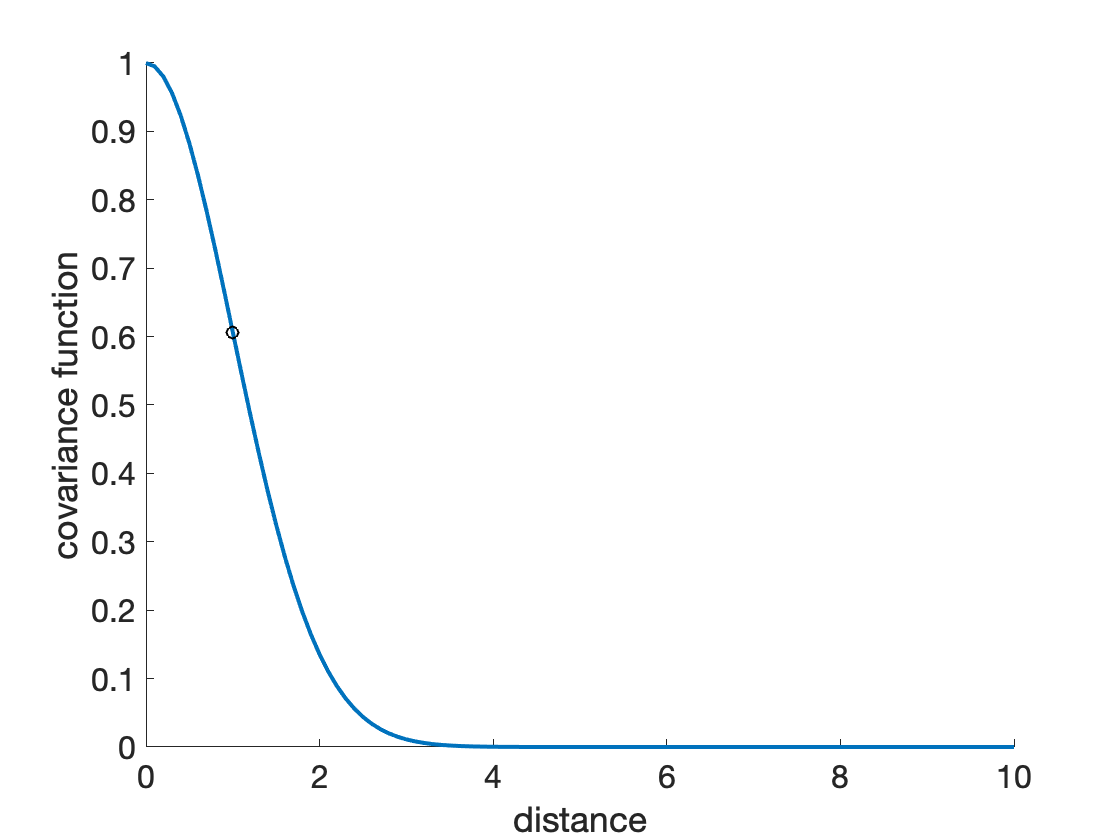

figure
hold on

plot(r, CovFx, 'LineWidth', 2)
plot(1/l, CovFxL, 'ok')

xlabel('distance')
ylabel('covariance function')
set(gca, 'FontSize', 16)

## Sensitivity for l

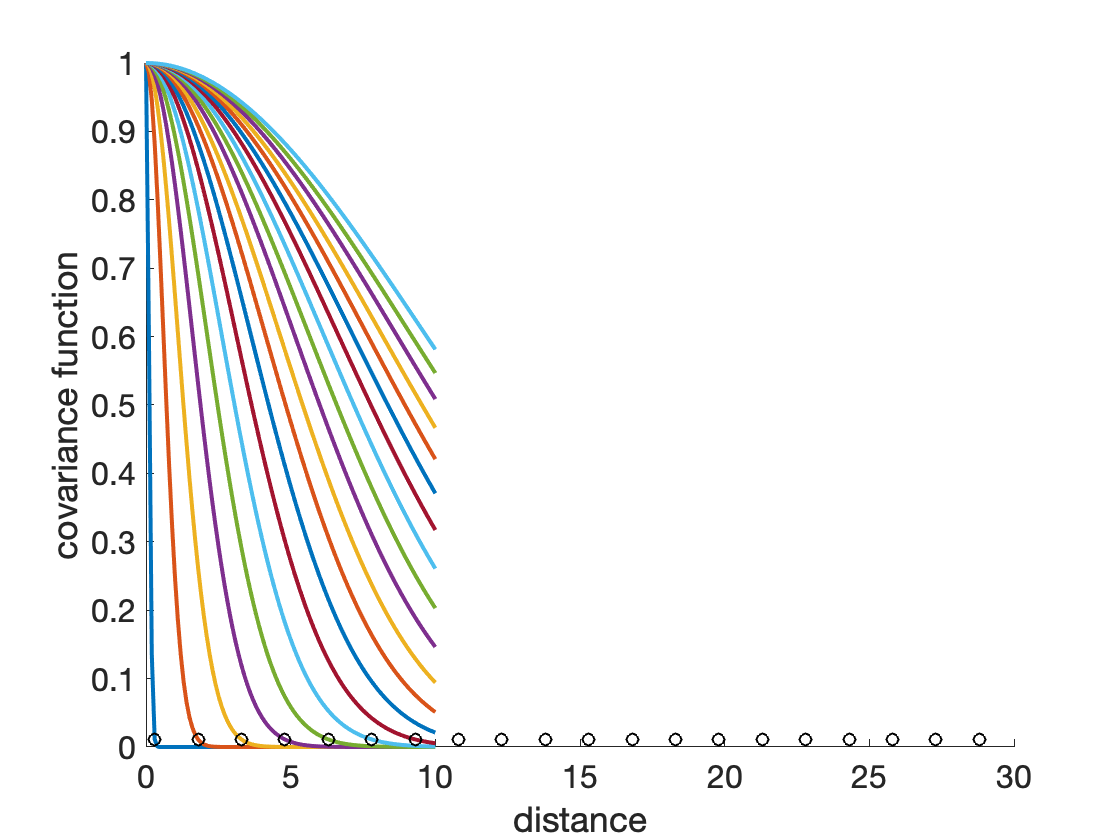

figure
hold on

ll = (0.1 : 0.5 : 10);
for l = ll
    plot(r, VarSignal * exp( -r.^2./(2*l.^2) ) + VarNoise, 'LineWidth', 2)
end

plot(3*ll, VarSignal * exp( -(3*ll).^2./(2*ll.^2) ) + VarNoise, 'ok')

xlabel('distance')
ylabel('covariance function')
set(gca, 'FontSize', 16)


% the covariance fx becomes equal to 0.01 at a distance equal to 3l.
% Therefore two inputs located a 3l distance are almost unrelated